OPERADORS MORFOLOGICS:

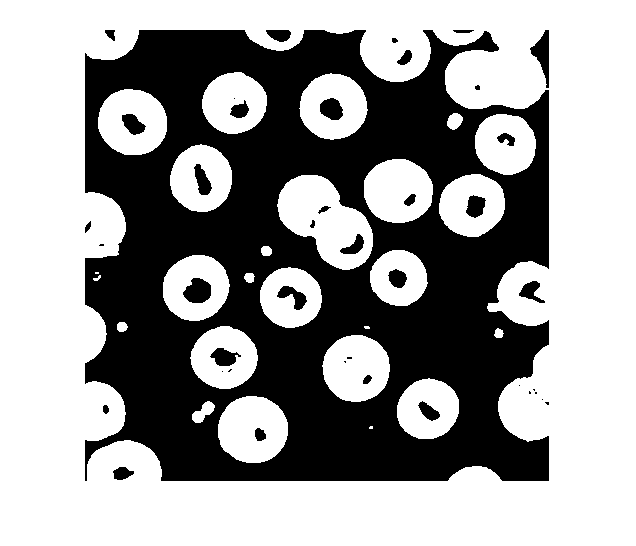

I = imread('blood5.tif');
B = I < 128;
imshow(B);

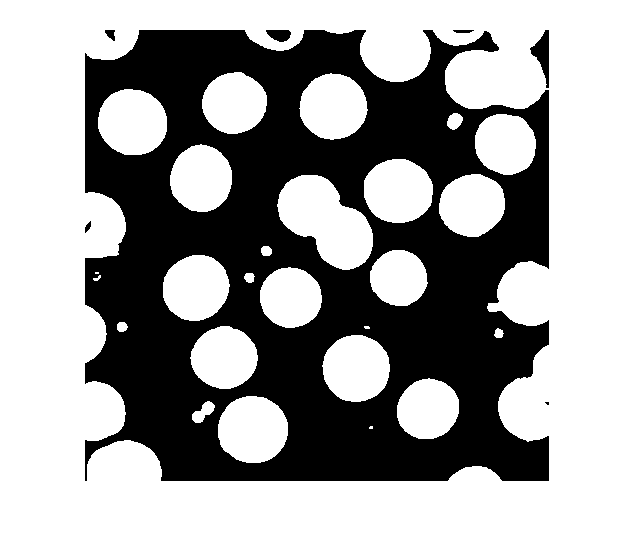

F = imfill(B, 'holes');
imshow(F);

El imfill analitza els veins per tal de determinar si es un forat i per tant emplenar-lo

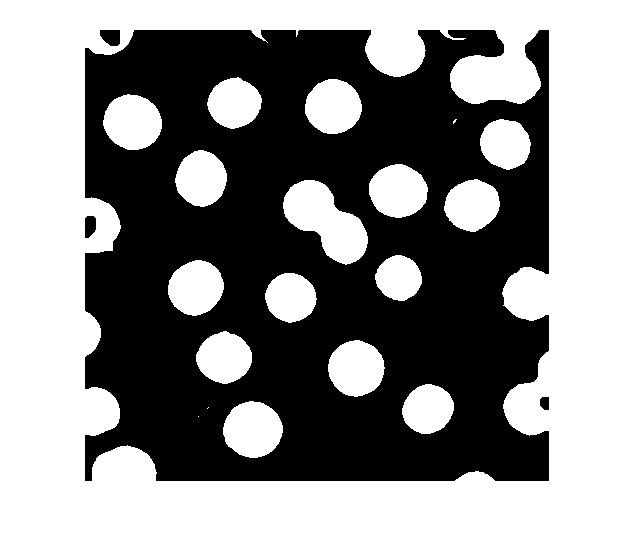

SE = strel('disk', 6);
E = imerode(F, SE);
imshow(E);

El valor de 6 indica el radi del disk, del element estructural, un cop analitzat mitjançant el strel fa l'erosió i es menja les vores, per tant separa part de les celules, ja que les fa petites. Com més erodes fem, mes es separàn o podem tmb fer el disk més gran.

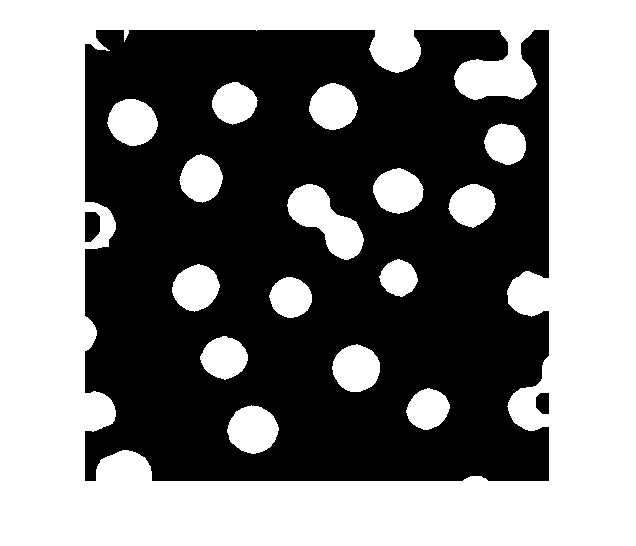

SE2 = strel('disk', 10);
E2 = imerode(F, SE2);
imshow(E2);

------------------ Nova imatge, passem a utilitzar grans de cafe

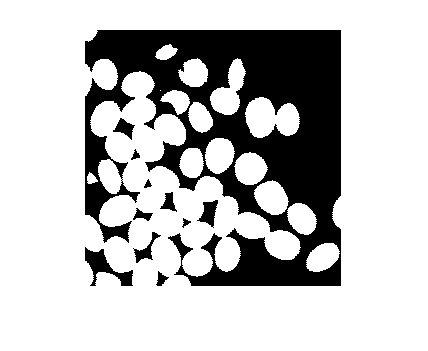

I = imread('cafe.tif');
B = I < 16; 
imshow(B);

Com els grans de café es toquen, els erosionem per tal de que es separin.

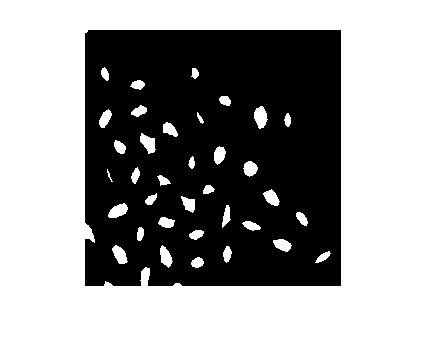

SEcafe = strel('disk', 9);
Ecafe = imerode(B, SEcafe);
imshow(Ecafe);

Això es molt poc precis, per tal de fer més precis farem el següent:

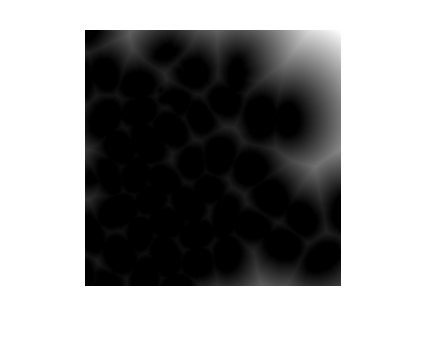

DT = bwdist(B, 'euclidean');
imshow(DT, []);

els objectes que estan a distancia 1 els posa com a 0 i els pixels que estàn fora del gra de café el marca com a 1. Les diagonals les marca com a arrel de 2, la manera euclidiana es més exacta i ens pot ser util per trobar el centre dels grans de café, si ho realitzem del revés, si enlloc de propagar desde els voltants del gra de café cap a fora, ho utilitzem de fora a dins. Com a continuació

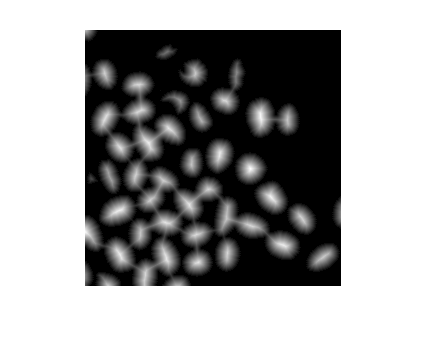

DT2 = bwdist(1-B, 'euclidean');
imshow(DT2, []);

C = DT2 > 10;
CC = bwconncomp(C);

Amb el valor de C, només ens mostrarà els grans de café amb centre més gran que 10. Per l'etiquetatje, utilitzem el CC, per tal de que ens dongui la llista dels objectes especificats.

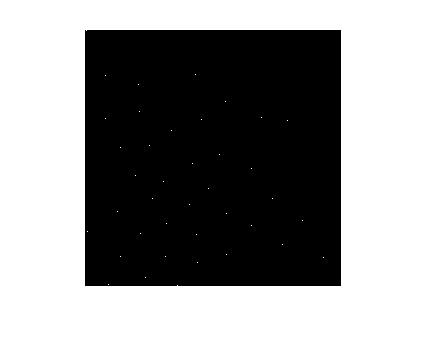

R = [regionprops(CC, 'centroid')];
NC = bwmorph(C, 'shrink', Inf);
imshow(NC);

Erosiona un pixel, fins al maxim (Infinit), apareix un pixel blanc per cada celula (teoricament)

--------------------- EXERCICI: crear un element estructural per tal de que detecti els pals i esborri tot el que no detecti com a pals

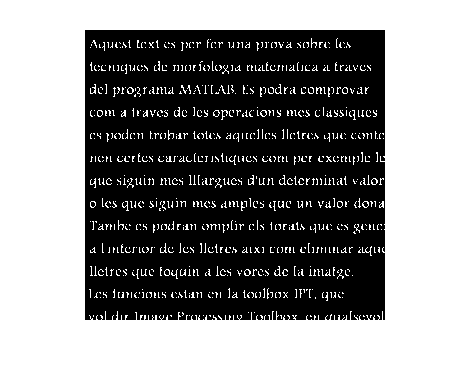

Imt = imread('text.tif');
Bin = Imt > 202;
imshow(Bin);

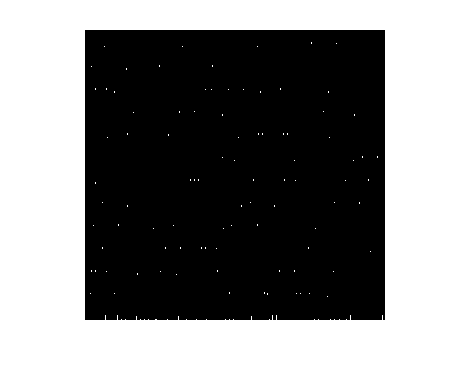

SE = strel('line',8,90);
Ero = imerode(Bin, SE);
imshow(Ero);

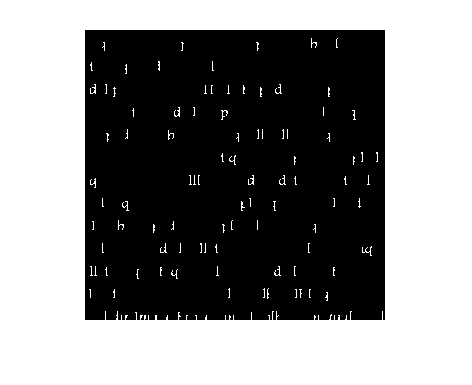

D = imreconstruct(Ero, Bin);
imshow(D);

reconstruct va creixent fins el limit que li determina la imatge original. S'ha de jugar amb la binarització per tal de que quedi bé

Exercici 1:

- Binaritzar i obtenir la roda, oplir forats amb infill i per contar les dents, erosionar les dents i quedar-nos unicament amb la roda (perque es menjarà totes les dents) i com vull quedarme amb les dents, fer la resta

- Han de donar 120 dents.

Exercici 2:

- Vull contar celules senceres, primer binaritzar. Despres s'han de treure les celules que toquen al marc de la imatge. Fent una imatge artificial amb tot el voltant a 1, i amb l'imreconstruct, es dilatarà per per tal de fer una imatge amb totes les celules marcades a les vores, si això o restem a la imatge original, les farem desapareixer, un cop aixo fem el labeling per tal de saber quantes hi ha.

Exercici 3:

-  Per tal de trobar la celula més aïllada, utilitzant operacions morfologiques estrictament. 

-  1 - Binaritzar

-  2 - Fer Shrink per tal de trobar els centres (imatge S, tindrem un pixel on estan les celules)

- 3 - skiz - son els pixels que estan més aprop d'un objecte. fem la transformada de la distancia, fem la and de la distancia transformada pel pixel central, imatge S i buscar el Max.